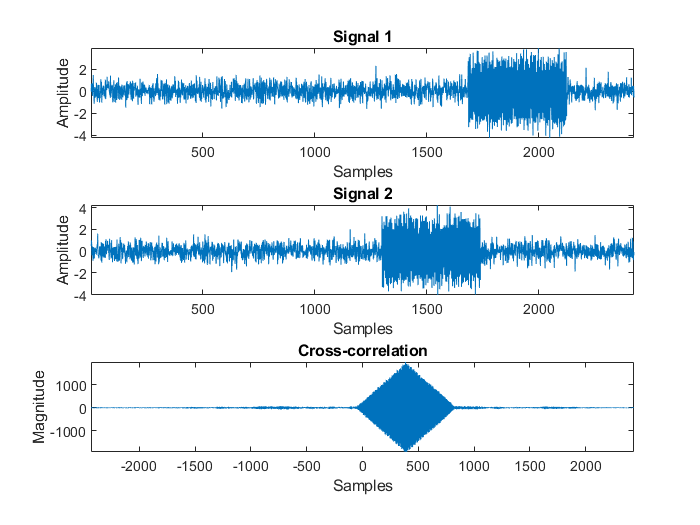

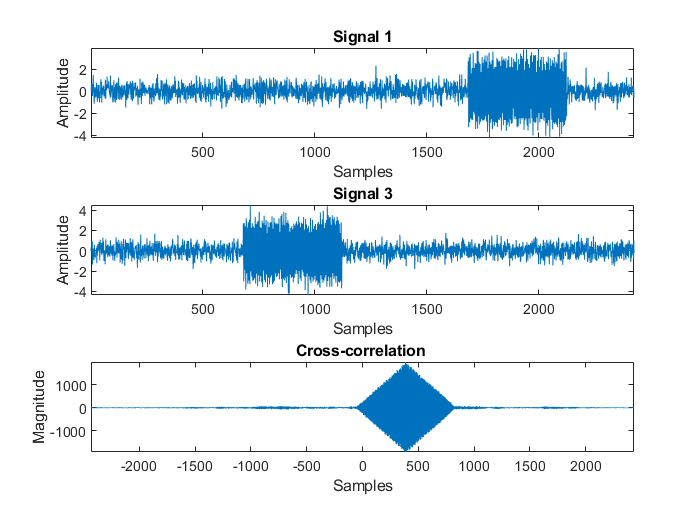

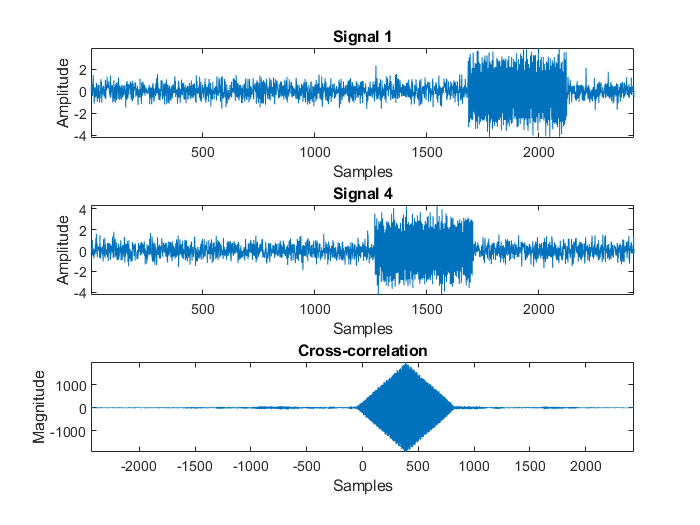

clear all
f=10000;
Fs=44100;
t=0:1/Fs:10e-3;
%n=[ 6080 , 5905 , 6045 , 6015];
%n=[1587,1450,1123,882];
n=[1696,1311,692,1279];
s=3*sin(2*pi*f*t);
s11=[zeros(1, n(1)) , s, zeros(1,300)] ;
s22=[zeros(1, n(2)) , s, zeros(1,length(s11)-n(2)-length(s))] ;
s33=[zeros(1, n(3)) , s, zeros(1,length(s11)-n(3)-length(s))];
s44=[zeros(1, n(4) ), s, zeros(1,length(s11)-n(4)-length(s))];
SNR=5;
s1=awgn(s11,SNR);
s2=awgn(s22,SNR);
s3=awgn(s33,SNR);
s4=awgn(s44,SNR);

x1=0; y1=0; z1=0;
x2=5; y2=0; z2=5;
x3=5; y3=5; z3=5;
x4=0; y4=5; z4=0;


x=[x1,x2,x3,x4];
y=[y1,y2,y3,y4];
z=[z1,z2,z3,z4];
%x_real=35; y_real=24;z_real=20;
x_real=7; y_real=10;z_real=5;
%semnale_timp(s1,s2,s3,s4,Fs);
Contents();
%fft_semnale(s1,s2,s3,s4,Fs);
[tdoa12_cr , tdoa13_cr, tdoa14_cr] = corelatia(s1,s2,s3,s4,Fs);

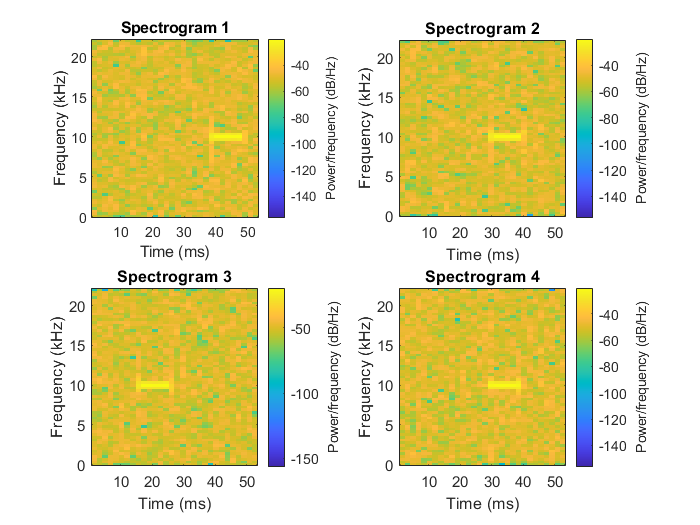

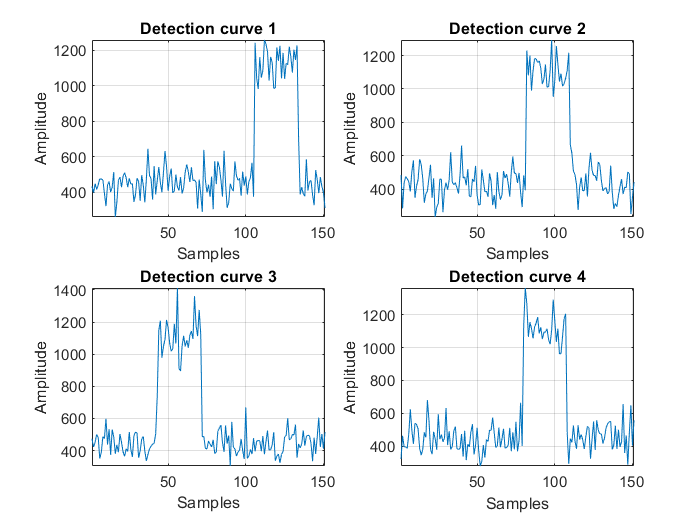

[tdoa12_sp,tdoa13_sp,tdoa14_sp]= spectrograma_s(s1,s2,s3,s4,Fs,0.4);

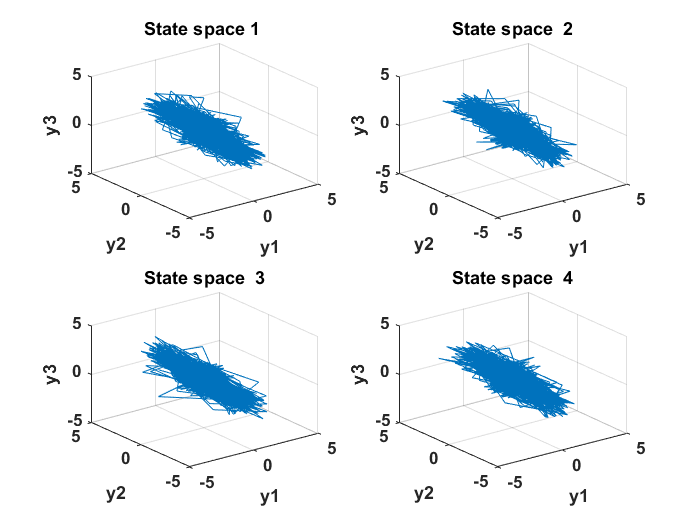

[tdoa12_rpa,tdoa13_rpa,tdoa14_rpa]=rpa(s1,s2,s3,s4,Fs,0.4);

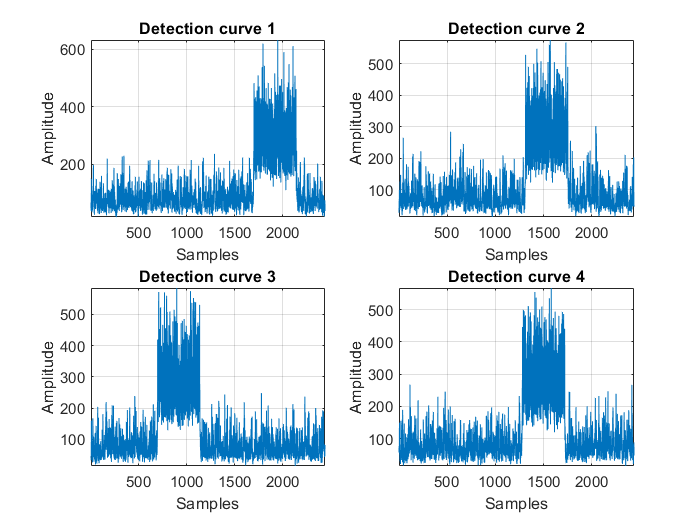

tdoa12_wave = 0.0375

tdoa13_wave = 0.0282

tdoa14_wave = 0.0359

[tdoa12_wave,tdoa13_wave,tdoa14_wave]=wavelet_s(s1,s2,s3,s4,Fs,0.4)

xs = 2.5038

ys = 2.5015

zs = 2.5038

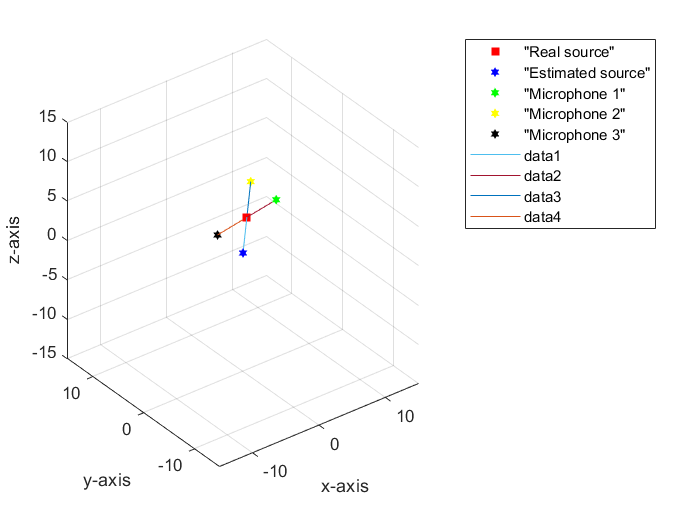

h =   Figure (16) with properties:

      Number: 16
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [489 343 560 420]
       Units: 'pixels'

  Show all properties


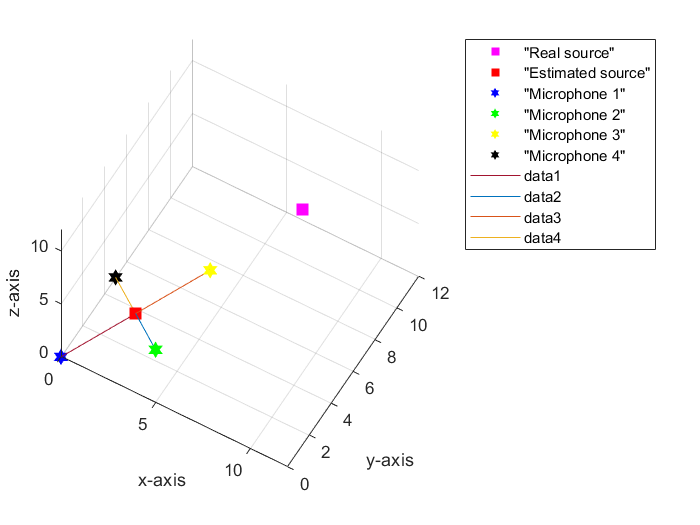

[xs_sp,ys_sp,zs_sp]=tdoa_sigur(tdoa12_sp,tdoa13_sp+0.000000001,tdoa14_sp,x1,x2,x3,x4,y1,y2,y3,y4,z1,z2,z3,z4,x_real,y_real,z_real);

xs = 6.0058

ys = 10.0137

zs = 6.0058

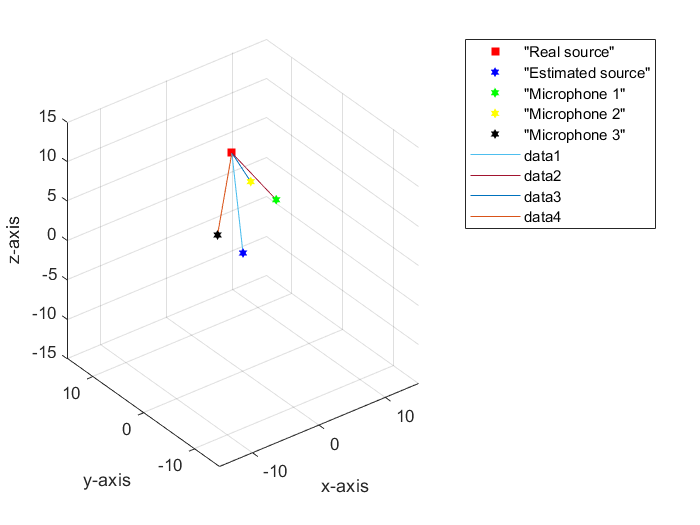

h =   Figure (18) with properties:

      Number: 18
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [489 343 560 420]
       Units: 'pixels'

  Show all properties


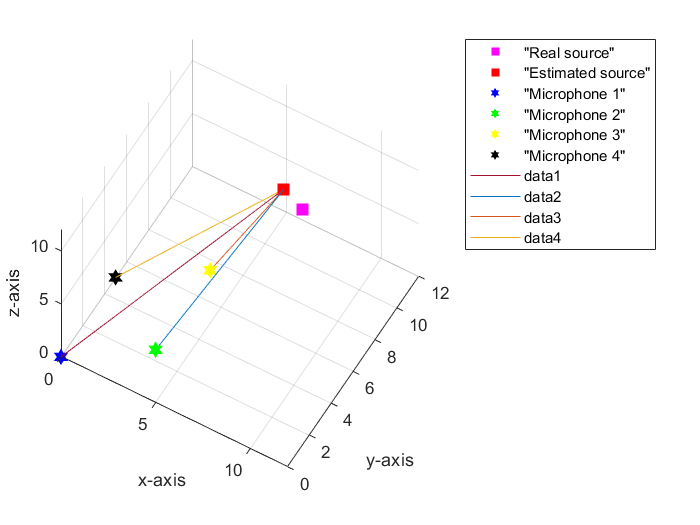

[xs_cor,ys_cor,zs_cor]=tdoa_sigur(tdoa12_cr,tdoa13_cr,tdoa14_cr,x1,x2,x3,x4,y1,y2,y3,y4,z1,z2,z3,z4,x_real,y_real,z_real);

xs = 6.0055

ys = 10.0458

zs = 6.0055

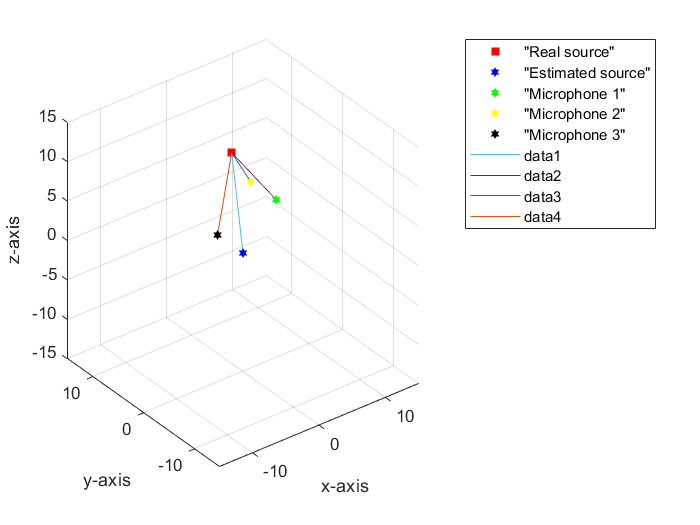

h =   Figure (20) with properties:

      Number: 20
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [489 343 560 420]
       Units: 'pixels'

  Show all properties


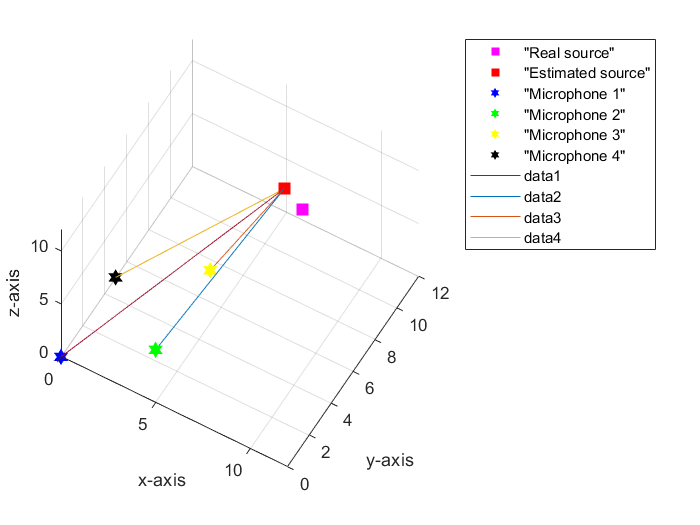

[xs_rpa,ys_rpa,zs_rpa]=tdoa_sigur(tdoa12_rpa,tdoa13_rpa,tdoa14_rpa,x1,x2,x3,x4,y1,y2,y3,y4,z1,z2,z3,z4,x_real,y_real,z_real);

xs = 3.5046

ys = 5.0950

zs = 3.5046

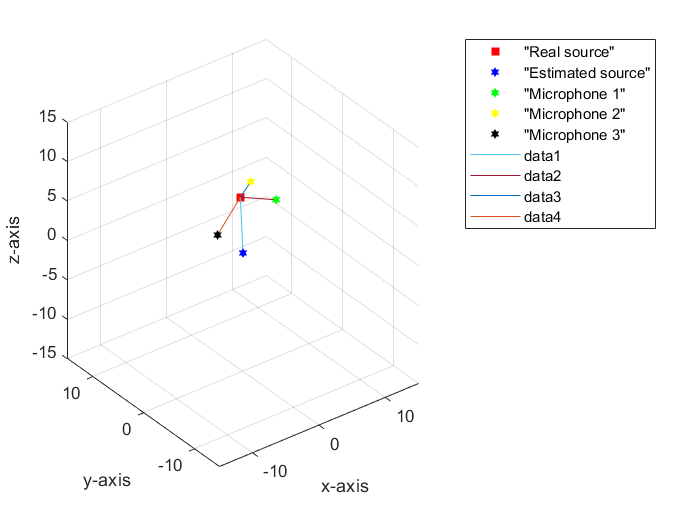

h =   Figure (22) with properties:

      Number: 22
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [489 343 560 420]
       Units: 'pixels'

  Show all properties


[xs_wav,ys_wav,zs_wav]=tdoa_sigur(tdoa12_wave,tdoa13_wave,tdoa14_wave,x1,x2,x3,x4,y1,y2,y3,y4,z1,z2,z3,z4,x_real,y_real,z_real);

A=["Cross-correlation",xs_cor,ys_cor,zs_cor];
B=["RPA",xs_rpa,ys_rpa,zs_rpa];
C=["Wavelet Transform",xs_wav,ys_wav,zs_wav];
D=["The Spectrogram",xs_sp,ys_sp,zs_sp];
E=["True position",x_real,y_real,z_real]

E = 1×4 string array
    "True position"    "7"    "10"    "5"


ERR=["Maximum error", abs(max(max(xs_cor-x_real,xs_rpa-x_real),max(xs_wav-x_real,xs_sp-x_real))), abs(max(max(ys_cor-y_real,ys_rpa-y_real),max(ys_wav-y_real,ys_sp-y_real))),abs(max(max(zs_cor-z_real,zs_rpa-z_real),max(zs_wav-z_real,zs_sp-z_real)))]

ERR = 1×4 string array
    "Maximum error"    "0.99419"    "0.045807"    "1.0058"


R=[E;A;B;C;D;ERR];
A1=[xs_cor,ys_cor,zs_cor];
% fileID = fopen('coordonate.txt','w');
% fprintf(fileID, 'S-a detectat o sursa acustica la coordonatele:\n');
% fprintf(fileID,'%6s %12s %18s\r\n','x','y','z');
% fprintf(fileID,'%6.2f %12.8f %18.2f\r\n',A1);
% type coordonate.txt;
T=array2table(R,'VariableNames',{'Method','x','y','z'})

T = 6×4 table
          Method               x            y            z    
    ___________________    _________    __________    ________

    "True position"        "7"          "10"          "5"     
    "Cross-correlation"    "6.0058"     "10.0137"     "6.0058"
    "RPA"                  "6.0055"     "10.0458"     "6.0055"
    "Wavelet Transform"    "3.5046"     "5.095"       "3.5046"
    "The Spectrogram"      "2.5038"     "2.5015"      "2.5038"
    "Maximum error"        "0.99419"    "0.045807"    "1.0058"


%send_email('cristina.popovici211@gmail.com','Sursa acustica detectata','S-a detectat o sursa acustica, deschideti fisierul pentru a viziona coordonatele:',{'C:\Users\Teo\Desktop\Licență\MATLAB\Licenta\coordonate.txt','C:\Users\Teo\Desktop\Licență\MATLAB\Licenta\Rezultate.jpg'})
